# Plot Fig. S6

addpath(genpath('../../public_code'))


nDays = 10;

nstrain = 'male_before_timp_180511'; nNodes = 15;
nEdges = nNodes*(nNodes-1)/2 ;
nStates = 4;

jij2_gd_before = zeros(nEdges, nDays);
hir2_gd_before = zeros((nStates-1)*nNodes, nDays);
dh2_gd_before = zeros(nNodes, nDays);


for iday = 1:nDays
    fpday = ['sme_6h_nbs10_pseudocount_' nstrain '_iday' num2str(iday) '_full6hr.mat'];  
    load(fpday,'jij_gd_eachday','hir_gd_eachday');
    jij2_gd_before(:, iday) = jij_gd_eachday;
    hir2_gd_before(:, iday) = hir_gd_eachday;
    hirMat = reshape(hir_gd_eachday, nNodes, nStates-1);
    dh_before = -(hirMat(:,1)+hirMat(:,3)-hirMat(:,2))';
    dh2_gd_before(:, iday) = dh_before;

end


%%
hirMat2 = zeros(nNodes, nStates, nDays);
for iday = 1:nDays
    hirMat2(:,1:3,iday) = reshape(hir2_gd_before(:,iday), nNodes, nStates-1);
end

hir2_gd_before = -squeeze(hirMat2(:,1,:)+hirMat2(:,3,:)-hirMat2(:,2,:))';


cday_jij = zeros(nDays, nDays);
for iday = 1:nDays
    for jday = iday+1:nDays
        cday_jij(iday, jday) = ...
            corr(jij2_gd_before(:,iday), jij2_gd_before(:,jday));
    end
end

ji2_gd_before = zeros(nNodes, nDays);
for iday = 1:nDays
    ji2_gd_before(:,iday) = ...
        sum(recoverUpt(jij2_gd_before(:,iday), nNodes));
end
cday_ji = zeros(nDays, nDays);
for iday = 1:nDays
    for jday = iday+1:nDays
        cday_ji(iday, jday) = ...
            corr(ji2_gd_before(:,iday), ji2_gd_before(:,jday));
    end
end

cday_hir = zeros(nDays, nDays);
for iday = 1:nDays
    for jday = iday+1:nDays
        cday_hir(iday, jday) = corr(hir2_gd_before(iday,:)',hir2_gd_before(jday,:)');
    end
end



## Fig. S6. A

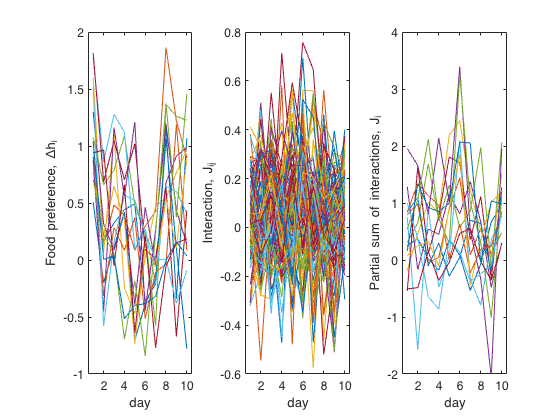

figure()

subplot(1,3,1)
plot(hir2_gd_before)
xlim([0.5 10.5])
xlabel('day')
set(gca,'fontsize',12)
ylabel('Food preference, \Deltah_{i}')

subplot(1,3,2)
plot(jij2_gd_before')
xlim([0.5 10.5])
xlabel('day')
set(gca,'fontsize',12)
ylabel('Interaction, J_{ij}')

subplot(1,3,3)
plot(ji2_gd_before')
ylim([-2 4])
xlim([0.5 10.5])

xlabel('day')
set(gca,'fontsize',12)
ylabel('Partial sum of interactions, J_{i}')

## Fig. S6. B

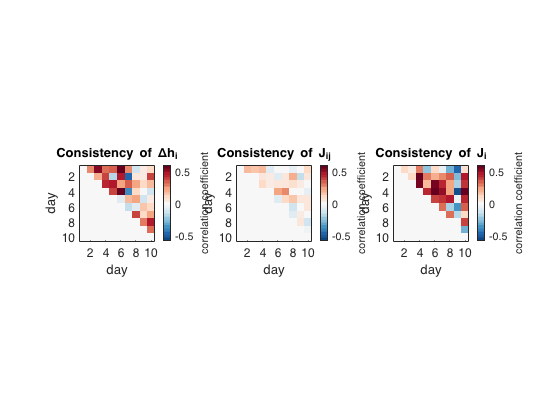

figure()
subplot(1,3,1)
imagesc(cday_hir)
colormap(redbluecmap(51))
c=colorbar();
caxis([-0.6 0.6])
axis square
xlabel('day')
ylabel('day')
set(gca,'fontsize',12)
ylabel(c, 'correlation coefficient')
title('Consistency of \Deltah_{i}')

subplot(1,3,2)
imagesc(cday_jij)
colormap(redbluecmap(51))
c=colorbar();
caxis([-0.6 0.6])
axis square
xlabel('day')
ylabel('day')
set(gca,'fontsize',12)
ylabel(c, 'correlation coefficient')
title('Consistency of J_{ij}')

subplot(1,3,3)
imagesc(cday_ji)
colormap(redbluecmap(51))
c=colorbar();
caxis([-0.6 0.6])
axis square
xlabel('day')
ylabel('day')
set(gca,'fontsize',12)
ylabel(c, 'correlation coefficient')
title('Consistency of J_{i}')

## Fig. S6.C

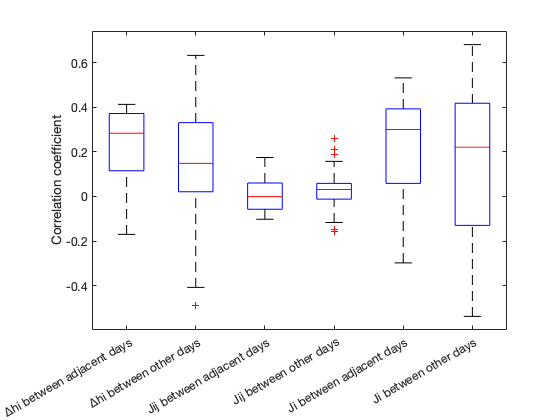

cday_shift_jij = zeros(nDays-1, 2);
crest_jij = [];
for dday = 1:nDays-1
    if dday > 1
        crest_jij = [crest_jij diag(cday_jij,dday)'];
    end
    cday_shift_jij(dday, 1) = mean(diag(cday_jij,dday));
    cday_shift_jij(dday, 2) = std(diag(cday_jij,dday));
end

%%
cday_shift_ji = zeros(nDays-1, 2);
crest_ji = [];
for dday = 1:nDays-1
    if dday > 1
        crest_ji = [crest_ji diag(cday_ji,dday)'];
    end
    cday_shift_ji(dday, 1) = mean(diag(cday_ji,dday));
    cday_shift_ji(dday, 2) = std(diag(cday_ji,dday));
end

cday_shift_hir = zeros(nDays-1, 2);
crest_hir = [];
for dday = 1:nDays-1
    if dday > 1
        crest_hir = [crest_hir diag(cday_hir,dday)'];
    end
    cday_shift_hir(dday, 1) = mean(diag(cday_hir,dday));
    cday_shift_hir(dday, 2) = std(diag(cday_hir,dday));
end

%%
figure()
g1 = repmat({'Δhi between adjacent days'},9,1);
g2 = repmat({'Δhi between other days'},36,1);
g3 = repmat({'Jij between adjacent days'},9,1);
g4 = repmat({'Jij between other days'},36,1);
g5 = repmat({'Ji between adjacent days'},9,1);
g6 = repmat({'Ji between other days'},36,1);

g = [g1; g2; g3; g4; g5; g6];

boxplot([diag(cday_hir,1)' crest_hir, ...
    diag(cday_jij,1)' crest_jij ...
    diag(cday_ji,1)' crest_ji],g)
set(gca,'fontsize',12)
ylabel('Correlation coefficient')